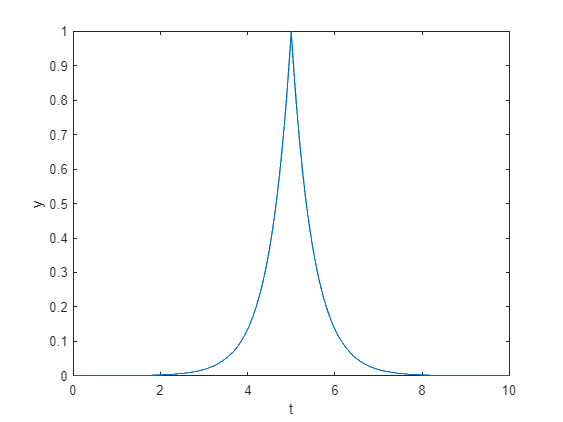

t = 0:tau:T-tau;
x = exp(2.*abs(t));
tau = 0.01; T=10;
y=zeros(1, length(t));
for k=1:length(t)
    if t(k)>=5
        y(k)=exp(-2*(t(k)-5));
    else
        y(k)=exp(2*(t(k)-5));
    end
end
N = length(y);
figure(1); plot(t,y); xlabel('t'); ylabel('y')

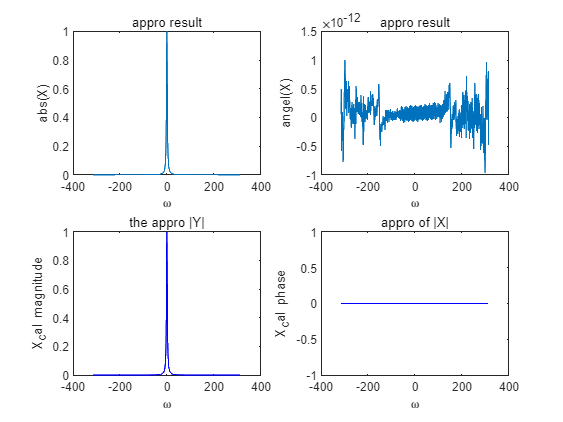

Y = fftshift(tau*fft(y));
w = -(pi/tau)+(0:N-1)*(2*pi/(N*tau));

for k=1:length(w)
    X(k)=exp(-1*j*5*w(k))*Y(k);
end
figure(2)
subplot(2,2,1); plot(w, abs(X)); xlabel('\omega'); ylabel('abs(X)');title('appro result')
subplot(2,2,2); plot(w, angle(X)); xlabel('\omega'); ylabel('angel(X)');title('appro result')
for k=1:length(w)
    X_cal = 1./(2+j*w) + 1./(2-j*w);
end
subplot(2,2,3);plot(w,abs(X_cal),'b'); xlabel('\omega');ylabel('X_cal magnitude'), title('the appro |Y|')
subplot(2,2,4);plot(w,angle(X_cal),'b'); xlabel('\omega');ylabel('X_cal phase'), title('appro of |X|')

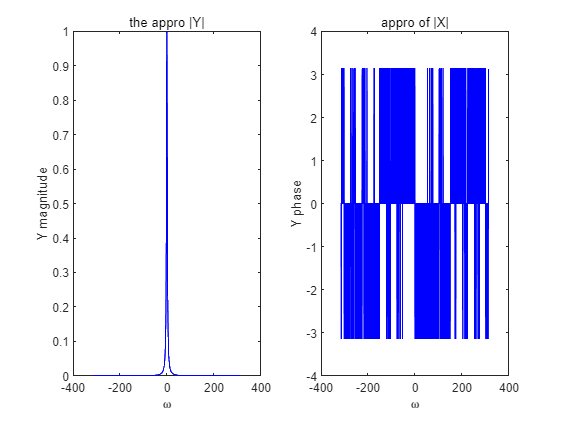

figure(3)
subplot(1,2,1);plot(w,abs(Y),'b'); xlabel('\omega');ylabel('Y magnitude'), title('the appro |Y|')
subplot(1,2,2);plot(w,angle(Y),'b'); xlabel('\omega');ylabel('Y phase'), title('appro of |X|')

# 4.6

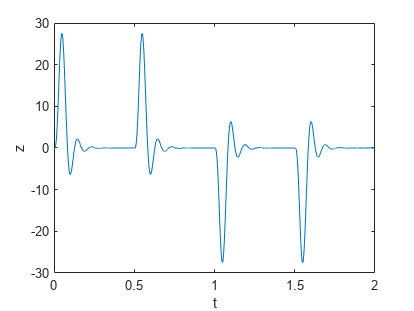

clc; clear; close all;

load('ctftmod.mat');

%(a)
z = [dash dash dot dot];
f46a = figure;
figure(f46a);
plot(t, z);xlabel('t');ylabel('z');

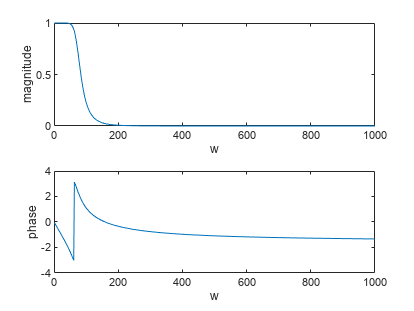

%(b)
[h, w_freqs] = freqs(bf, af);

f46b = figure;
figure(f46b);
subplot(211);plot(w_freqs, abs(h)); xlabel('w'); ylabel('magnitude');
subplot(212);plot(w_freqs, angle(h)); xlabel('w'); ylabel('phase');

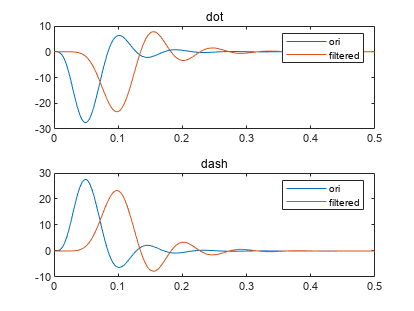

%(c)
N = length(dot);
ydash = lsim(bf, af, dash, t(1:N));
ydot = lsim(bf, af, dot, t(1:N));

f46c = figure;
figure(f46c);
subplot(211);plot(t(1:N), dot, t(1:N), ydot);title('dot');legend('ori', 'filtered');
subplot(212);plot(t(1:N), dash, t(1:N), ydash);title('dash');legend('ori', 'filtered');

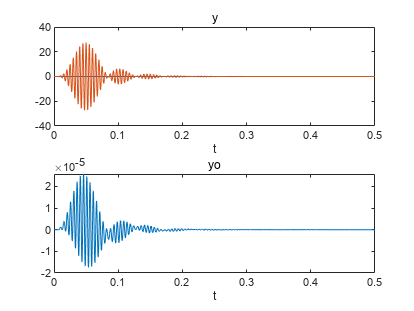

%(d)
y = dash.*cos(2*pi*f1*t(1:length(dash)));
yo = lsim(bf,af,y,t(1:length(dash)));

f46d = figure;
figure(f46d);
subplot(211);plot(t(1:N), yo, t(1:N), y); xlabel('t'); title('y');
subplot(212);plot(t(1:N), yo); xlabel('t'); title('yo');

the yo is 

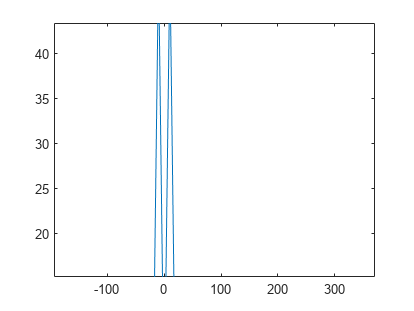

%(e)
Fs = 1000;
L = 100;
t = (0:L-1)*(1/Fs);
x = cos(2*pi*10*t);
y = fft(x);
ysh = fftshift(y);
f = (-L/2:L/2-1)*Fs/L;
figure;
plot(f,abs(ysh));